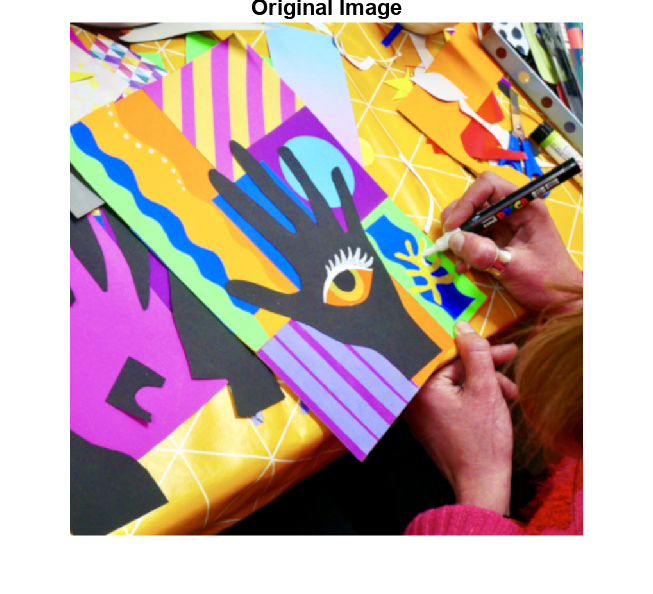

clear
clf

% Settings
partitionSize = 50;

% Load hex colors from file and put in an array
file = fileread('diverse-natural.hex');
hexColors = strsplit(file, '\n');
hexColors = hexColors(~cellfun('isempty',hexColors));
rgbColors = cellfun(@hex2rgb, hexColors, 'UniformOutput', false);

% Read shape image
[circle, ~, alpha] = imread('circle.png');

% Apply color to the shape and display it
% circle = colorshape(rgbColors{50}, circle);
% hImage = imshow(circle);
% set(hImage, 'AlphaData', alpha);

im = imread("hand.jpg");
[rows, cols, ~] = size(im);

for i = 1:partitionSize:rows
    for j = 1:partitionSize:cols
        % Define the current block's end row and column
        endRow = min(i + partitionSize - 1, rows);
        endCol = min(j + partitionSize - 1, cols);

        % Extract the current block
        currentBlock = im(i:endRow, j:endCol, :);

        % Calculate the mean color of the current block
        meanColor = mean(mean(currentBlock, 1), 2);
        
        % Cast the mean color to uint8
        meanColor = uint8(meanColor);



        % Convert mean color to CIELAB and
        % calculate distance between mean CIELAB and palette CIELAB ?
        % and fetch the closest color



        % Apply the mean color to the current block in the modified image
        for k = 1:3 % For each color channel
            modifiedIm(i:endRow, j:endCol, k) = meanColor(:,:,k);
        end
           
    end
end

imshow(im);
title('Original Image');

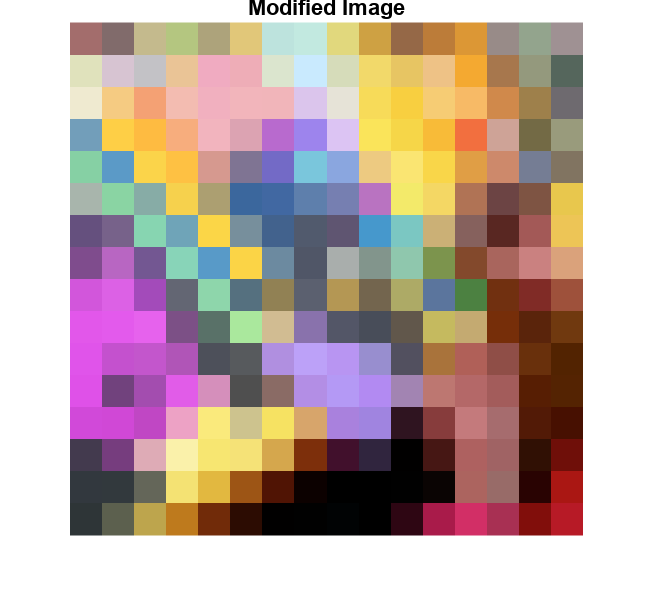


imshow(modifiedIm);
title('Modified Image');